% Set a Working Tolerance 
tol = 0.06;


% Create image

ZI = peaks(40);

% Create a referencing matrix

R = [0 1; 1 0; 0 0];

% Select VIP points

ZImask = vipmask(ZI,tol,true);

% Create the TIN from the image, refmat, and mask

[tri, x, y, z] = dem2tin(ZI,R,ZImask);

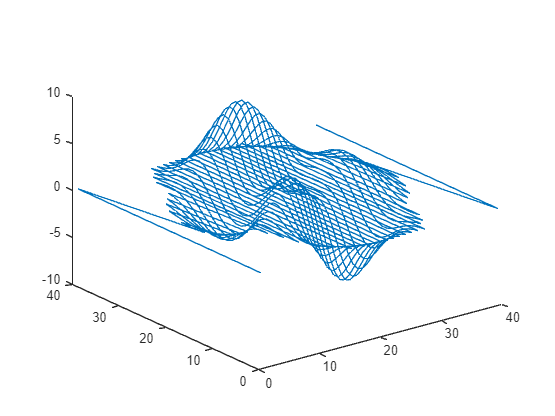

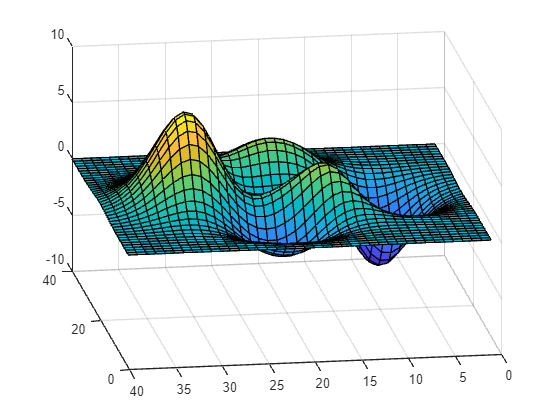


% Check error

[ZIe, ZIn] = verifytin(ZI,R,x,y,z);